# **GM(1,1)模型**

**原始数据级比检验**

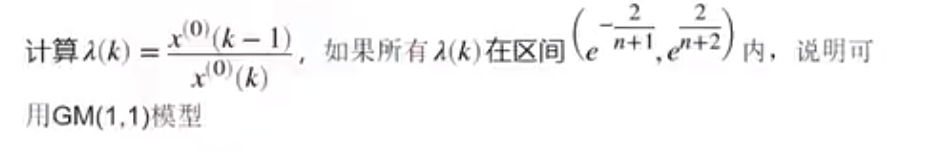

x0 = [71.1 72.4 72.4 72.1 71.4 72.0 71.6]; %列向量
n = length(x0);
lamda = x0(1:n-1)./x0(2:n); % 计算级比
range = minmax(lamda'); % 级比范围
lamrang_min = exp(-2/(n+1)); % 允许的下界
lamrang_max = exp(2/(n+2)); % 允许的上界
if (range(1) > lamrang_min && range(2) < lamrang_max)
    fprintf("原始数据通过级比检验")
else 
    fprintf("原始数据未通过级比检验")
    return
end

原始数据通过级比检验

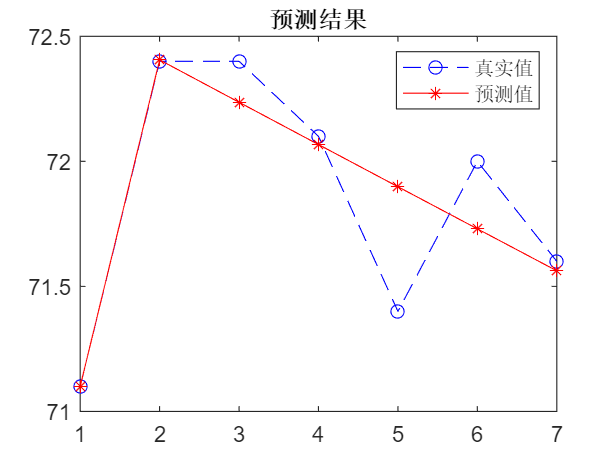

syms a u;
c=[a,u]';%构成矩阵
A= x0;%输入数据，可以修改
Ago=cumsum(A);%原始数据一次累加,得到1-AGO序列xi(1)。
n=length(A);%原始数据个数
for k=1:(n-1)
    Z(k)=(Ago(k)+Ago(k+1))/2; %Z(i)为xi(1)的紧邻均值生成序列
end
Yn =A;%Yn为常数项向量
Yn(1)=[]; %从第二个数开始，即x(2),x(3)...
Yn=Yn';
E=[-Z;ones(1,n-1)]';%累加生成数据做均值
c=(E'*E)\(E'*Yn);%利用公式求出a，u
c= c';
a=c(1);%得到a的值
u=c(2);%得到u的值
F=[];
F(1)=A(1);
for k=2:(n)
    F(k)=(A(1)-u/a)/exp(a*(k-1))+u/a;%求出GM(1,1)模型公式
end
G=[];
G(1)=A(1);
for k=2:(n)
    G(k)=F(k)-F(k-1);%两者做差还原原序列，得到预测数据
end
t1=1:n;
t2=1:n;
plot(t1,A,'bo--');
hold on;
plot(t2,G,'r*-'); 
title('预测结果');
legend('真实值','预测值');

%后验差检验
e=A-G;
q=e/A;%相对误差
s1=var(A);
s2=var(e);
c=s2/s1;%方差比
len=length(e);
p=0;  %小误差概率
for i=1:len
    if(abs(e(i))<0.6745*s1)
        p=p+1;
    end
end
p=p/len;